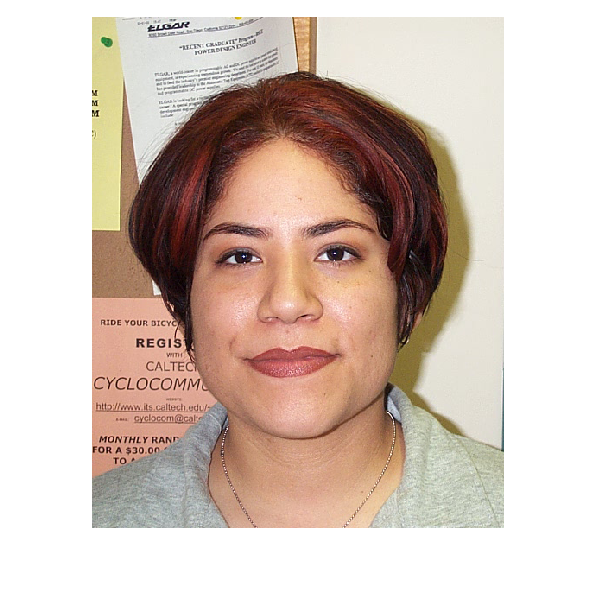

C1 = imread('../TNM034/Facial-recognition/db/DB0/db0_1.jpg');
imshow(C1);


% Dela upp färgkanalerna
r = C1(:,:,1); % Röd kanal
g = C1(:,:,2); % Grön kanal
b = C1(:,:,3); % Blå kanal

% Beräkna maxvärden för varje kanal
r_max = max(max(r));
g_max = max(max(g));
b_max = max(max(b));

% Beräkna faktorer för att balansera kanalerna
alfa = g_max/r_max;
beta = g_max/b_max;

% Justera färgkanalerna med faktorerna
r_sensor = alfa.*r;
g_sensor = g;
b_sensor = beta.*b;

% Visa den justerade bilden
whiteworld_img = cat(3, r_sensor, g_sensor, b_sensor);
imshow(whiteworld_img)

%imwrite(whiteworld_img,'../TNM034/Facial-recognition/facedetection/whiteworld.png')

